close all
clear
clc

syms x y gamma c real

r=c^(2/(gamma-1))

$$r = c^{\frac{2}{\gamma -1}}$$


V=sqrt(2*(1-c^2)/(gamma-1))

$$V = \sqrt{-\frac{2\,c^{2}-2}{\gamma -1}}$$


J=1/c+1/(3*c^3)+1/(5*c^5)-1/2*log((1+c)/(1-c))

$$J = \frac{1}{c}-\frac{\log\left(-\frac{c+1}{c-1}\right)}{2}+\frac{1}{3\,c^{3}}+\frac{1}{5\,c^{5}}$$


psi=sqrt(1/(2*V^2)+r*(x+J/2))

$$psi = \sqrt{c^{\frac{2}{\gamma -1}}\,\left(x-\frac{\log\left(-\frac{c+1}{c-1}\right)}{4}+\frac{1}{2\,c}+\frac{1}{6\,c^{3}}+\frac{1}{10\,c^{5}}\right)-\frac{\gamma -1}{2\,\left(2\,c^{2}-2\right)}}$$


vx=-sign(y)*V*psi*V

$$vx = \frac{\mathrm{sign}\left(y\right)\,\sqrt{c^{\frac{2}{\gamma -1}}\,\left(x-\frac{\log\left(-\frac{c+1}{c-1}\right)}{4}+\frac{1}{2\,c}+\frac{1}{6\,c^{3}}+\frac{1}{10\,c^{5}}\right)-\frac{\gamma -1}{2\,\left(2\,c^{2}-2\right)}}\,\left(2\,c^{2}-2\right)}{\gamma -1}$$


vy=V*sqrt(1-(psi*V)^2)

$$vy = \sqrt{-\frac{2\,c^{2}-2}{\gamma -1}}\,\sqrt{1-\frac{\left(\frac{\gamma -1}{2\,\left(2\,c^{2}-2\right)}-c^{\frac{2}{\gamma -1}}\,\left(x-\frac{\log\left(-\frac{c+1}{c-1}\right)}{4}+\frac{1}{2\,c}+\frac{1}{6\,c^{3}}+\frac{1}{10\,c^{5}}\right)\right)\,\left(2\,c^{2}-2\right)}{\gamma -1}}$$


p=1/gamma*c^(2*gamma/(gamma-1))

$$p = \frac{c^{\frac{2\,\gamma }{\gamma -1}}}{\gamma }$$


eqC=(x+J/2)^2+y^2==1/(4*r^2*V^4)

$$eqC = {\left(x-\frac{\log\left(-\frac{c+1}{c-1}\right)}{4}+\frac{1}{2\,c}+\frac{1}{6\,c^{3}}+\frac{1}{10\,c^{5}}\right)}^{2}+y^{2}=\frac{{\left(\gamma -1\right)}^{2}}{4\,c^{\frac{4}{\gamma -1}}\,{\left(2\,c^{2}-2\right)}^{2}}$$


gamma=1.4

gamma = 1.4000


[x,y]=meshgrid(linspace(1e-6,1,11));

eqC=eval(eqC);

tic
c=eval(arrayfun(@(eq) vpasolve(eq,c,1/2),eqC));
toc

Elapsed time is 5.900979 seconds.


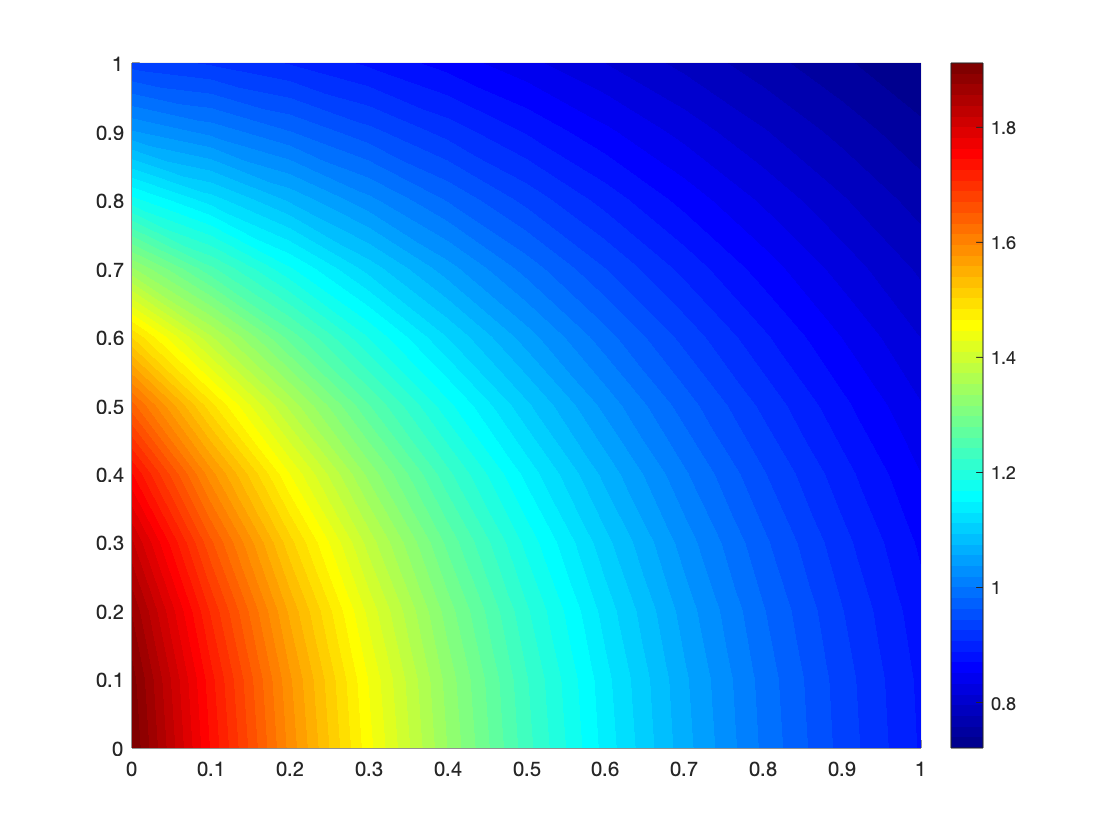


M=eval(sqrt(vx.^2+vy.^2))./c;

surf(x,y,M)
shading interp
colormap(jet(64))
colorbar
view(2)
xlim([0,1])
ylim([0,1])